clc;
clear;
close all;

## Esercizio 1

generi un numero n intero positivo tra 10 e 20 in modo pseudo-random e costruisca n vettori colonna di lunghezza n ciascuno contenente i numeri da 1 a n.

Successivamente si costruisca la matrice A di dimensione n × n ottenuta affiancando i vettori creati precedentemente. Infine, si calcolino e si visualizzino il determinante di A, il suo spettro e le sue norme con indice 1, 2 e ∞;

n = randi([10 20])
A = zeros(n);
for i = 1:n
    v = (1 : 1 : n)';
    A(:, i) = v;
end
A

fprintf("Determinante: %d", det(A));
% Autovalori e autovettori della matrice
[V, D] = eig(A);
spettro = diag(D)

norma1 = norm(A, 1)
norma2 = norm(A)
normaInf = norm(A, inf)

clc;
clear;
close all;

## Esercizio 2

crei la matrice dei coefficienti di un sistema lineare `Ax = b` con numeri pseudo-casuali reali compresi tra −10 e 10 di dimensione 10×10 e controlli se è invertibile. In caso positivo, imponga una soluzione nota x di elementi uguali a 1 e calcoli il corrispondente termine noto b. Successivamente, risolva il sistema lineare e calcoli e visualizzi l’errore relativo tra la soluzione vera x e quella ottenuta x1 . Se la matrice A non dovesse risultare invertibile, dovrà esserne generata una nuova fino a quando si ottiene una matrice non singolare;

iMin = -10;
iMax = 10;
n = 10;
flag = true;
while flag
    A = (iMax-iMin) * rand(n) + iMin
    if (abs(det(A)) < 1e-10)
        disp("Non e' invertibile")
    else
        flag = false;
        x = ones(10, 1);
        b = A * x
        x1 = A\b
    
        errRel = norm(x - x1) / norm(x)
    end
end

clc;
clear;
close all;

## Esercizio 3

implementi un test per l’approssimazione della radice positiva dell’equazione nonlineare

utilizzando il metodo di bisezione, con intervallo iniziale [1, 2] e con il metodo di Newton, con punto iniziale x0 = 1. Infine si stampi, sullo stesso sistema di assi cartesiani, il grafico della funzione f (x) e le due approssimazioni ottenute.

f = @(x) cos(pi .* x ./ 4) - 4 .* x .* x + 4;
f1 = @(x) -sin((pi/4)./x).*(pi/4) - 8.*x;

tau = 10e-5;
x0 = 1;

[xb, kb] = bisezione(f, 1, 2, tau, 100);
[xn, kn] = newton(f, f1, x0, tau, 100);

x = linspace(0, 2, 100),

x =          0    0.0202    0.0404    0.0606    0.0808    0.1010    0.1212    0.1414    0.1616    0.1818    0.2020    0.2222    0.2424    0.2626    0.2828    0.3030    0.3232    0.3434    0.3636    0.3838    0.4040    0.4242    0.4444    0.4646    0.4848    0.5051    0.5253    0.5455    0.5657    0.5859    0.6061    0.6263    0.6465    0.6667    0.6869    0.7071    0.7273    0.7475    0.7677    0.7879    0.8081    0.8283    0.8485    0.8687    0.8889    0.9091    0.9293    0.9495    0.9697    0.9899


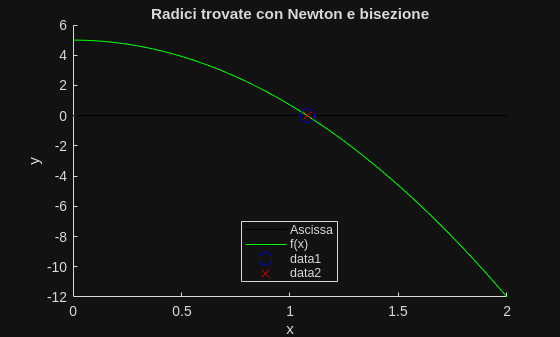


figure;
hold on;

title("Radici trovate con Newton e bisezione");
xlabel("x");
ylabel("y");

plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xn, f(xn), "Ob", "MarkerSize", 10);
plot(xb, f(xb), "Xr", "MarkerSize", 8);

legend("Location", "best");
hold off;

function [xb, kb] = bisezione(f, a, b, tau, kmax)
    
    % bisezione: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0 
    %   [xb, kb] = bisezione(f, a, b, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo la variabile fa con f(a) per non doverla calcolare più
    % volte
    fa = f(a);

    % Controllo che nell'intervallo sia contenuta la radice che cerco
    if(fa * f(b) > 0)
        error("Nessuna radice nell'intervallo [%g, %g]", a, b);
    end


    % Inizio algoritmo iterativo da k a kmax
    for kb = 1 : kmax
       
        % Formula bisezione
        xb = (a + b) / 2;
        
        % Aggiorno l'immagine della x trovata per non doverla calcolare più
        % volte
        fxb = f(xb);

        % Controllo la positività dell'immagine trovata e aggiorno
        % l'intervallo
        if(fa * fxb < 0)
            b = xb;
        else
            a = xb;
            fa = fxb;
        end
        
        % Condizioni di arresto
        if abs(fxb) < tau
            return;
        end

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end

function [xn, kn] = newton(f, fder, x0, tau, kmax)

    % newton: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0
    %   [xn, kn] = newton(f, fder, x0, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo xn
    xn = x0;

    % Se il punto passato è già soluzione lo restituisco
    if(abs(f(x0)) < tau)
        kn = 0;
        return;
    end

    % Inizio algoritmo iterativo da k a kmax
    for kn = 1 : kmax
        
        f1 = fder(x0);

        if(abs(f1) < tau)
            error("La derivata tende a 0: cambia il valore x0");
        end

        % Formula Newton
        xn = x0 - f(x0) / f1;

        % Condizioni di arresto: se la soluzione non è variata
        % significativamente dall'iterazione precedente o se l'immagine
        % risulta abbastanza vicina a 0
        if abs(f(xn)) < tau || abs(xn - x0) < tau * abs(x0)
            return;
        end

        % Aggiornamento variabili
        x0 = xn;

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end